clear all
figure

data = readtable("Optimisation4.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______


resultTab1 = data{:, :};
resultTab1 = resultTab1(:,[11,12,13])

resultTab1 =    -1.7583   -1.7918    2.0499
   -2.0369   -1.7918    2.6449
    0.4446   -1.9459    2.0469
   -0.7768   -1.9459    1.9696
   -0.2340   -1.7918    0.8529
   -0.6510   -1.9459    2.3556
    0.0072   -1.9459    2.5100
   -0.5022   -1.9459    2.4904
   -0.3481   -1.7918    1.2538
    0.1621   -1.9459    1.4706



resultTab1(:,1) = exp(-resultTab1(:,1))

resultTab1 =     5.8027   -1.7918    2.0499
    7.6671   -1.7918    2.6449
    0.6411   -1.9459    2.0469
    2.1745   -1.9459    1.9696
    1.2637   -1.7918    0.8529
    1.9174   -1.9459    2.3556
    0.9928   -1.9459    2.5100
    1.6523   -1.9459    2.4904
    1.4164   -1.7918    1.2538
    0.8504   -1.9459    1.4706


resultTab1(:,2) = exp(-resultTab1(:,2))

resultTab1 =     5.8027    6.0000    2.0499
    7.6671    6.0000    2.6449
    0.6411    7.0000    2.0469
    2.1745    7.0000    1.9696
    1.2637    6.0000    0.8529
    1.9174    7.0000    2.3556
    0.9928    7.0000    2.5100
    1.6523    7.0000    2.4904
    1.4164    6.0000    1.2538
    0.8504    7.0000    1.4706


resultTab1(:,3) = -exp(resultTab1(:,3))

resultTab1 =     5.8027    6.0000   -7.7670
    7.6671    6.0000  -14.0825
    0.6411    7.0000   -7.7436
    2.1745    7.0000   -7.1678
    1.2637    6.0000   -2.3463
    1.9174    7.0000  -10.5446
    0.9928    7.0000  -12.3049
    1.6523    7.0000  -12.0657
    1.4164    6.0000   -3.5037
    0.8504    7.0000   -4.3517



utopiaPoint1 = [max(resultTab1(:,1)), max(resultTab1(:,2)), max(resultTab1(:,3))]

utopiaPoint1 =     7.6671    7.0000   -1.9937


antiutopiaPointTemp = [min(resultTab1(:,1)), min(resultTab1(:,2)), min(resultTab1(:,3))]

antiutopiaPointTemp =     0.2623    6.0000  -14.0825



antiutopiaPointCorr = 0.01.*(utopiaPoint1-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0740    0.0100    0.1209


antiutopiaPoint1 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint1 =     0.1882    5.9900  -14.2034



data = readtable("Optimisation5.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______


resultTab2 = data{:, :};
resultTab2 = resultTab2(:,[11,12,13])

resultTab2 =    -0.6970   -1.9459    1.6285
    0.4371   -1.9459    2.5872
    0.4105   -1.9459    1.4989
    0.0070   -1.9459    2.4750
   -0.5102   -1.9459    2.5233
   -1.2863   -1.7918    2.1888
   -0.3084   -1.7918    1.3098
    0.0636   -1.9459    1.5350
   -0.2144   -1.9459    2.0855
   -0.1888   -1.7918    1.0532



resultTab2(:,1) = exp(-resultTab2(:,1))

resultTab2 =     2.0076   -1.9459    1.6285
    0.6459   -1.9459    2.5872
    0.6633   -1.9459    1.4989
    0.9931   -1.9459    2.4750
    1.6656   -1.9459    2.5233
    3.6192   -1.7918    2.1888
    1.3612   -1.7918    1.3098
    0.9384   -1.9459    1.5350
    1.2391   -1.9459    2.0855
    1.2078   -1.7918    1.0532


resultTab2(:,2) = exp(-resultTab2(:,2))

resultTab2 =     2.0076    7.0000    1.6285
    0.6459    7.0000    2.5872
    0.6633    7.0000    1.4989
    0.9931    7.0000    2.4750
    1.6656    7.0000    2.5233
    3.6192    6.0000    2.1888
    1.3612    6.0000    1.3098
    0.9384    7.0000    1.5350
    1.2391    7.0000    2.0855
    1.2078    6.0000    1.0532


resultTab2(:,3) = -exp(resultTab2(:,3))

resultTab2 =     2.0076    7.0000   -5.0962
    0.6459    7.0000  -13.2921
    0.6633    7.0000   -4.4767
    0.9931    7.0000  -11.8814
    1.6656    7.0000  -12.4696
    3.6192    6.0000   -8.9247
    1.3612    6.0000   -3.7056
    0.9384    7.0000   -4.6412
    1.2391    7.0000   -8.0488
    1.2078    6.0000   -2.8669



utopiaPoint2 = [max(resultTab2(:,1)), max(resultTab2(:,2)), max(resultTab2(:,3))]

utopiaPoint2 =     3.6192    7.0000   -2.0399


antiutopiaPointTemp = [min(resultTab2(:,1)), min(resultTab2(:,2)), min(resultTab2(:,3))]

antiutopiaPointTemp =     0.5779    6.0000  -13.2921



antiutopiaPointCorr = 0.01.*(utopiaPoint2-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0304    0.0100    0.1125


antiutopiaPoint2 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint2 =     0.5475    5.9900  -13.4047



data = readtable("Optimisation6.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph    RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    ________    __________________    __________________    _________________    ______________________    ________<


resultTab3 = data{:, :};
resultTab3 = resultTab3(:,[11,12,13])

resultTab3 =     0.3071   -1.9459    1.9270
   -0.4678   -1.9459    1.8442
   -0.7088   -1.9459    2.1860
    0.3579   -1.9459    1.9763
    0.8509   -1.9459    2.4039
   -0.4438   -1.9459    2.4387
   -0.2431   -1.7918    1.1727
   -0.7107   -1.9459    2.0382
   -0.6842   -1.9459    2.4257
   -0.5082   -1.9459    1.5379



resultTab3(:,1) = exp(-resultTab3(:,1))

resultTab3 =     0.7356   -1.9459    1.9270
    1.5965   -1.9459    1.8442
    2.0316   -1.9459    2.1860
    0.6991   -1.9459    1.9763
    0.4270   -1.9459    2.4039
    1.5586   -1.9459    2.4387
    1.2751   -1.7918    1.1727
    2.0353   -1.9459    2.0382
    1.9823   -1.9459    2.4257
    1.6622   -1.9459    1.5379


resultTab3(:,2) = exp(-resultTab3(:,2))

resultTab3 =     0.7356    7.0000    1.9270
    1.5965    7.0000    1.8442
    2.0316    7.0000    2.1860
    0.6991    7.0000    1.9763
    0.4270    7.0000    2.4039
    1.5586    7.0000    2.4387
    1.2751    6.0000    1.1727
    2.0353    7.0000    2.0382
    1.9823    7.0000    2.4257
    1.6622    7.0000    1.5379


resultTab3(:,3) = -exp(resultTab3(:,3))

resultTab3 =     0.7356    7.0000   -6.8686
    1.5965    7.0000   -6.3227
    2.0316    7.0000   -8.8994
    0.6991    7.0000   -7.2157
    0.4270    7.0000  -11.0665
    1.5586    7.0000  -11.4580
    1.2751    6.0000   -3.2308
    2.0353    7.0000   -7.6771
    1.9823    7.0000  -11.3097
    1.6622    7.0000   -4.6548



utopiaPoint3 = [max(resultTab3(:,1)), max(resultTab3(:,2)), max(resultTab3(:,3))]

utopiaPoint3 =     2.1073    7.0000   -1.9204


antiutopiaPointTemp = [min(resultTab3(:,1)), min(resultTab3(:,2)), min(resultTab3(:,3))]

antiutopiaPointTemp =     0.3944    6.0000  -14.3853



antiutopiaPointCorr = 0.01.*(utopiaPoint3-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0171    0.0100    0.1246


antiutopiaPoint3 = antiutopiaPointTemp - antiutopiaPointCorr

antiutopiaPoint3 =     0.3773    5.9900  -14.5099




utopiaPoint = max([utopiaPoint1; utopiaPoint2; utopiaPoint3])

utopiaPoint =     7.6671    7.0000   -1.9204


antiutopiaPoint = min([antiutopiaPoint1;antiutopiaPoint2;antiutopiaPoint3])

antiutopiaPoint =     0.1882    5.9900  -14.5099


%Optimisation 4
subplot(1,3,1)

paretoF = paretoFront([resultTab1(:,1) resultTab1(:,2) resultTab1(:,3)])

paretoF =     5.8027    6.0000   -7.7670
    7.6671    6.0000  -14.0825
    2.1945    7.0000   -2.7993
    1.4644    7.0000   -2.0401
    2.2006    7.0000   -3.0029
    1.0379    7.0000   -1.9937



% scatter3(resultTab1(:,1), resultTab1(:,2), resultTab1(:,3), "bo", "filled")
% 
% hold on
% scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
% scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
% scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
% hold off

allHV = [];
for x = 7:length(resultTab1(:,1))

    paretoF = paretoFront([resultTab1(1:x,1) resultTab1(1:x,2) resultTab1(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1585
   -0.1585
   -0.1585
   -0.1780
   -0.2241
   -0.2241
   -0.2241
   -0.2241
   -0.2241
   -0.2246


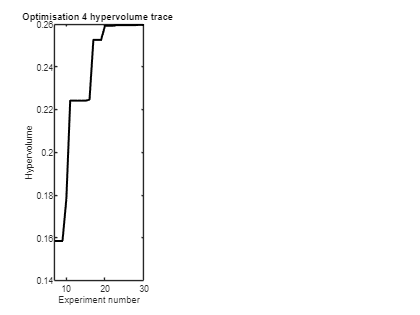


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 4 hypervolume trace ")
ylim([0.14 0.26])

%Optimisation 5
subplot(1,3,2)

paretoF = paretoFront([resultTab2(:,1) resultTab2(:,2) resultTab2(:,3)])

paretoF =     3.6192    6.0000   -8.9247
    1.4948    7.0000   -2.2675
    1.4788    7.0000   -2.0399
    1.9980    7.0000   -2.6785
    2.0493    7.0000   -4.5528
    2.0266    7.0000   -3.5349
    2.0313    7.0000   -4.0774



% scatter3(resultTab2(:,1), resultTab2(:,2), resultTab2(:,3), "bo", "filled")
% 
% hold on
% scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
% scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
% scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
% hold off

allHV = [];
for x = 7:length(resultTab2(:,1))

    paretoF = paretoFront([resultTab2(1:x,1) resultTab2(1:x,2) resultTab2(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1867
   -0.1871
   -0.1874
   -0.1874
   -0.1934
   -0.2127
   -0.2128
   -0.2302
   -0.2326
   -0.2330


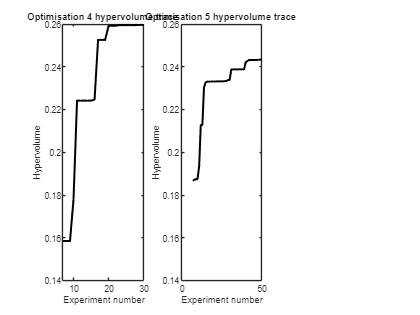


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 5 hypervolume trace ")
ylim([0.14 0.26])

%Optimisation 6
subplot(1,3,3)

paretoF = paretoFront([resultTab3(:,1) resultTab3(:,2) resultTab3(:,3)])

paretoF =     1.4373    7.0000   -2.1662
    1.0445    7.0000   -2.0689
    2.0771    7.0000   -3.2381
    1.3476    6.0000   -1.9204
    1.8447    7.0000   -2.4056
    2.1073    7.0000   -3.5919



% scatter3(resultTab3(:,1), resultTab3(:,2), resultTab3(:,3), "bo", "filled")
% 
% hold on
% scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
% scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
% scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
% hold off

allHV = [];
for x = 7:length(resultTab3(:,1))

    paretoF = paretoFront([resultTab3(1:x,1) resultTab3(1:x,2) resultTab3(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1486
   -0.1542
   -0.1546
   -0.1814
   -0.1815
   -0.1910
   -0.1910
   -0.2116
   -0.2116
   -0.2120


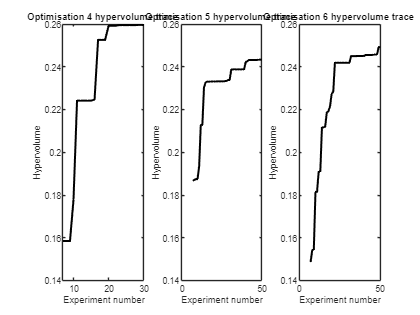


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 6 hypervolume trace ")
ylim([0.14 0.26])